### TASK 1A

**[Import Data]**

% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 6);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["site_code", "measurement_id", "TIME", "TEMP", "Press_ATM", "CO2EQ_PPM"];
opts.VariableTypes = ["categorical", "double", "string", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "TIME", "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["site_code", "TIME"], "EmptyFieldRule", "auto");

% Import the data
Project_Data = readtable("/Users/samanthadufumulleruri/Documents/UCL/YEAR 1/ENGF0003 - Mathematical Modelling and Analysis/Assessments/2 MATLAB COURSEWORK 2/DATA/Project_Data (1).csv", opts);

% Clear temporary variables
clear opts

% Display results
Project_Data

Project_Data = 172200×6 table
    site_code    measurement_id             TIME              TEMP     Press_ATM    CO2EQ_PPM
    _________    ______________    ______________________    ______    _________    _________

     NRSMAI          12943         "2020-05-22T06:00:00Z"    13.513      101.8       387.35  
     NRSMAI          12944         "2020-05-22T08:00:00Z"    13.554     101.84       385.32  
     NRSMAI          12945         "2020-05-22T10:00:00Z"    13.585     101.87       385.27  
     NRSMAI          12946         "2020-05-22T12:00:00Z"    13.571     101.86       384.79  
     NRSMAI          12947         "2020-05-22T14:00:00Z"      13.5     101.81       385.32  
     NRSMAI          12948         "2020-05-22T16:00:00Z"    13.455     101.72       384.53  
     NRSMAI  

**[Transforming Table Data]**

Project_Data

Project_Data = 172200×6 table
    site_code    measurement_id             TIME              TEMP     Press_ATM    CO2EQ_PPM
    _________    ______________    ______________________    ______    _________    _________

     NRSMAI          12943         "2020-05-22T06:00:00Z"    13.513      101.8       387.35  
     NRSMAI          12944         "2020-05-22T08:00:00Z"    13.554     101.84       385.32  
     NRSMAI          12945         "2020-05-22T10:00:00Z"    13.585     101.87       385.27  
     NRSMAI          12946         "2020-05-22T12:00:00Z"    13.571     101.86       384.79  
     NRSMAI          12947         "2020-05-22T14:00:00Z"      13.5     101.81       385.32  
     NRSMAI          12948         "2020-05-22T16:00:00Z"    13.455     101.72       384.53  
     NRSMAI  

% Alternatively Temperature0 = Project_Data(:,"TEMP")
project = Project_Data(Project_Data.site_code == "GBRWIS",:)

project = 59943×6 table
    site_code    measurement_id             TIME              TEMP     Press_ATM    CO2EQ_PPM
    _________    ______________    ______________________    ______    _________    _________

     GBRWIS          64494         "2020-03-06T08:00:00Z"    28.311     100.54       515.91  
     GBRWIS          64495         "2020-03-06T10:00:00Z"    28.492     100.66       497.84  
     GBRWIS          64496         "2020-03-06T12:00:00Z"    28.431      100.7       518.11  
     GBRWIS          64497         "2020-03-06T14:00:00Z"    28.394     100.66       488.41  
     GBRWIS          64498         "2020-03-06T16:00:00Z"    28.388     100.52       513.25  
     GBRWIS          64499         "2020-03-06T18:00:00Z"    28.367     100.52       525.28  
     GBRWIS        

% remember to convert from ATM (which is a unit of standard pressure?) into kPa and MPa when required)
temperature = project.TEMP

temperature =    28.3112
   28.4924
   28.4309
   28.3940
   28.3878
   28.3671
   28.4621
   28.4035
   28.4561
   29.8525


% Defining an Array for the Incompatible Values of Time in the Raw Data:

time0 = project.TIME

time0 = 59943×1 string array
    "2020-03-06T08:00:00Z"
    "2020-03-06T10:00:00Z"
    "2020-03-06T12:00:00Z"
    "2020-03-06T14:00:00Z"
    "2020-03-06T16:00:00Z"
    "2020-03-06T18:00:00Z"
    "2020-03-06T20:00:00Z"
    "2020-03-06T22:00:00Z"
    "2020-03-07T00:00:00Z"
    "2020-03-07T02:00:00Z"
    "2020-03-07T04:00:00Z"
    "2020-03-07T06:00:00Z"
    "2020-03-07T08:00:00Z"
    "2020-03-07T10:00:00Z"
    "2020-03-07T12:00:00Z"
    "2020-03-07T14:00:00Z"
    "2020-03-07T16:00:00Z"
    "2020-03-07T18:00:00Z"
    "2020-03-07T20:00:00Z"
    "2020-03-07T22:00:00Z"
    "2020-03-08T00:00:00Z"
    "2020-03-08T02:00:00Z"
    "2020-03-08T04:00:00Z"
    "2020-03-08T06:00:00Z"
    "2020-03-08T08:00:00Z"
    "2020-03-08T10:00:00Z"
    "2020-03-08T12:00:00Z"
    "2020-03-08T14:00:00Z"
    "2020-03-08T16:00:00Z"
    "2020-03-08T18:00:00Z"


% Time0 = convertTo(D,dateType)
% Time = years(Time0)
% Time = (zeros(length(Time0),1))
% Time = ((Time+1).*[0:1:172199]').*2

time = datetime((time0), 'InputFormat','yyyy-MM-dd''T''HH:mm:ss''Z','TimeZone','UTC')

time = 59943×1 datetime array
   06-Mar-2020 08:00:00
   06-Mar-2020 10:00:00
   06-Mar-2020 12:00:00
   06-Mar-2020 14:00:00
   06-Mar-2020 16:00:00
   06-Mar-2020 18:00:00
   06-Mar-2020 20:00:00
   06-Mar-2020 22:00:00
   07-Mar-2020 00:00:00
   07-Mar-2020 02:00:00
   07-Mar-2020 04:00:00
   07-Mar-2020 06:00:00
   07-Mar-2020 08:00:00
   07-Mar-2020 10:00:00
   07-Mar-2020 12:00:00
   07-Mar-2020 14:00:00
   07-Mar-2020 16:00:00
   07-Mar-2020 18:00:00
   07-Mar-2020 20:00:00
   07-Mar-2020 22:00:00
   08-Mar-2020 00:00:00
   08-Mar-2020 02:00:00
   08-Mar-2020 04:00:00
   08-Mar-2020 06:00:00
   08-Mar-2020 08:00:00
   08-Mar-2020 10:00:00
   08-Mar-2020 12:00:00
   08-Mar-2020 14:00:00
   08-Mar-2020 16:00:00
   08-Mar-2020 18:00:00


time = sortrows(time)

time = 59943×1 datetime array
   09-Oct-2009 06:00:00
   09-Oct-2009 09:00:00
   09-Oct-2009 12:00:00
   09-Oct-2009 15:00:00
   09-Oct-2009 18:00:00
   09-Oct-2009 21:00:00
   10-Oct-2009 00:00:00
   10-Oct-2009 03:00:00
   10-Oct-2009 06:00:00
   10-Oct-2009 09:00:00
   10-Oct-2009 12:00:00
   10-Oct-2009 15:00:00
   10-Oct-2009 18:00:00
   10-Oct-2009 21:00:00
   11-Oct-2009 00:00:00
   11-Oct-2009 03:00:00
   11-Oct-2009 06:00:00
   11-Oct-2009 09:00:00
   11-Oct-2009 12:00:00
   11-Oct-2009 15:00:00
   11-Oct-2009 18:00:00
   11-Oct-2009 21:00:00
   12-Oct-2009 00:00:00
   12-Oct-2009 03:00:00
   12-Oct-2009 06:00:00
   12-Oct-2009 09:00:00
   12-Oct-2009 12:00:00
   12-Oct-2009 15:00:00
   12-Oct-2009 18:00:00
   12-Oct-2009 21:00:00


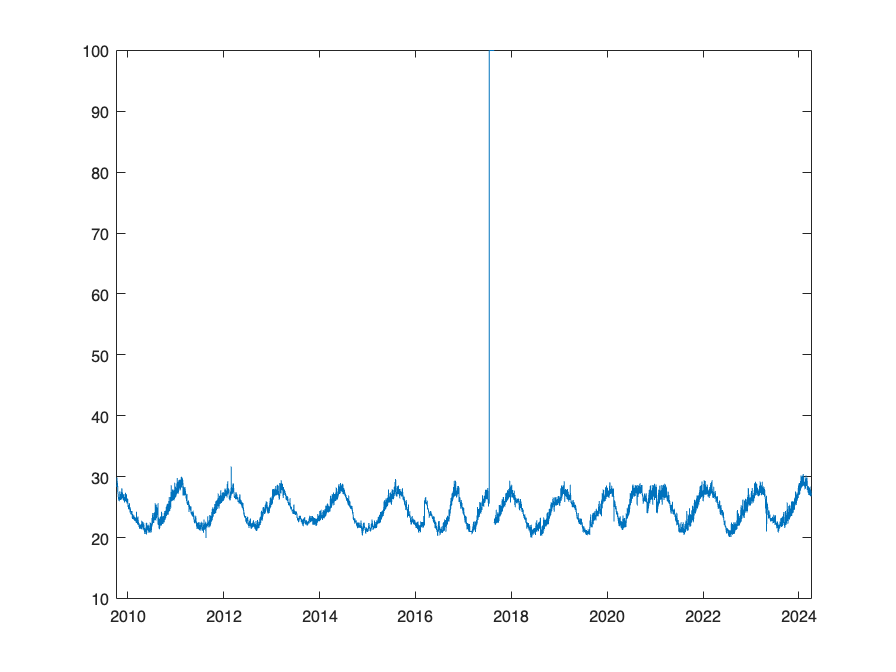

plot(time,temperature)

**Expressing Equations as a Linear Matrix System **

% TASK 1A

% Expressing Equations as a Linear Matrix System:
% syms function allows you to mathematically compute undefined variables

syms x_1 x_2 y_1 y_2 phi_1 phi_2 P_v1 P H_21
A = [P_v1 0 -phi_1*P 0; 0 H_21 0 -phi_2*P; 1 1 0 0; 0 0 1 1]

$$A = \left(\begin{array}{cccc} P_{\mathrm{v1}} & 0 & -P\,\varphi_{1} & 0\\ 0 & H_{21} & 0 & -P\,\varphi_{2}\\ 1 & 1 & 0 & 0\\ 0 & 0 & 1 & 1 \end{array}\right)$$

M_r = [0 0 1 1]'

M_r =      0
     0
     1
     1


M_xy = (A^-1) * M_r

$$M\_xy = \begin{array}{l} \left(\begin{array}{c} \frac{H_{21}\,\varphi_{1}}{\sigma_{1}}-\frac{P\,\varphi_{1}\,\varphi_{2}}{\sigma_{1}}\\ \frac{P\,\varphi_{1}\,\varphi_{2}}{\sigma_{1}}-\frac{P_{\mathrm{v1}}\,\varphi_{2}}{\sigma_{1}}\\ \sigma_{2}-\frac{P_{\mathrm{v1}}\,\varphi_{2}}{\sigma_{1}}\\ \frac{H_{21}\,\varphi_{1}}{\sigma_{1}}-\sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=H_{21}\,\varphi_{1}-P_{\mathrm{v1}}\,\varphi_{2}\\ \sigma_{2}=\frac{H_{21}\,P_{\mathrm{v1}}}{H_{21}\,P\,\varphi_{1}-P\,P_{\mathrm{v1}}\,\varphi_{2}} \end{array}$$

**TASK 1C**

**Analysing Under Which Conditions This Linear Matrix System is Invalid**

% TASK 1C

% Analysing Under Which Conditions This Linear Matrix System is Invalid:

syms x_3 y_3 phi_3 H_321
A_2 = [P_v1 0 0 -phi_1*P 0 0; 0 H_321 0 0 -phi_2*P 0;0 0 H_321 0 0 -phi_3...
    *P; 1 1 1 0 0 0; 0 0 0 1 1 1]

$$A\_2 = \left(\begin{array}{cccccc} P_{\mathrm{v1}} & 0 & 0 & -P\,\varphi_{1} & 0 & 0\\ 0 & H_{321} & 0 & 0 & -P\,\varphi_{2} & 0\\ 0 & 0 & H_{321} & 0 & 0 & -P\,\varphi_{3}\\ 1 & 1 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & 1 & 1 \end{array}\right)$$

M_r2_knowns = [0 0 0 1 1]'

M_r2_knowns =      0
     0
     0
     1
     1


M_r2_unknowns = [(x_1*P_v1)-(y_1*phi_1*P);(x_2*H_321)-(y_2*phi_2*P);(x_3*...
    H_321)-(y_3*phi_3*P);x_1+x_2+x_3;y_1+y_2+y_3]

$$M\_r2\_unknowns = \left(\begin{array}{c} P_{\mathrm{v1}}\,x_{1}-P\,\varphi_{1}\,y_{1}\\ H_{321}\,x_{2}-P\,\varphi_{2}\,y_{2}\\ H_{321}\,x_{3}-P\,\varphi_{3}\,y_{3}\\ x_{1}+x_{2}+x_{3}\\ y_{1}+y_{2}+y_{3} \end{array}\right)$$

M_xy2 = [x_1; x_2; x_3; y_1; y_2; y_3]

$$M\_xy2 = \left(\begin{array}{c} x_{1}\\ x_{2}\\ x_{3}\\ y_{1}\\ y_{2}\\ y_{3} \end{array}\right)$$